gnet=googlenet

gnet =   DAGNetwork with properties:

         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]
     InputNames: {'data'}
    OutputNames: {'output'}


lgraph = layerGraph(gnet)

lgraph =   LayerGraph with properties:

     InputNames: {'data'}
    OutputNames: {'output'}
         Layers: [144×1 nnet.cnn.layer.Layer]
    Connections: [170×2 table]



lgraph = removeLayers(lgraph,lgraph.Layers(end).Name)

lgraph =   LayerGraph with properties:

     InputNames: {'data'}
    OutputNames: {1×0 cell}
         Layers: [143×1 nnet.cnn.layer.Layer]
    Connections: [169×2 table]


dlnet = dlnetwork(lgraph)

dlnet =   dlnetwork with properties:

         Layers: [143×1 nnet.cnn.layer.Layer]
    Connections: [169×2 table]
     Learnables: [116×3 table]
          State: [0×3 table]
     InputNames: {'data'}
    OutputNames: {'prob'}
    Initialized: 1

  View summary with summary.


classes = categories(gnet.Layers(end).Classes)

classes = 1000×1 cell array
    {'tench'                   }
    {'goldfish'                }
    {'great white shark'       }
    {'tiger shark'             }
    {'hammerhead'              }
    {'electric ray'            }
    {'stingray'                }
    {'cock'                    }
    {'hen'                     }
    {'ostrich'                 }
    {'brambling'               }
    {'goldfinch'               }
    {'house finch'             }
    {'junco'                   }
    {'indigo bunting'          }
    {'robin'                   }
    {'bulbul'                  }
    {'jay'                     }
    {'magpie'                  }
    {'chickadee'               }
    {'water ouzel'             }
    {'kite'                    }
    {'bald eagle'              }
    {'vulture'                 }
    {'great grey owl'          }
    {'European fire salamander'}
    {'common newt'             }
    {'eft'                     }
    {'spotted salamander'      }
    {'axolotl' 

img = imread('panda.jpg');
T = "giant panda";
inputSize = dlnet.Layers(1).InputSize

inputSize =    224   224     3


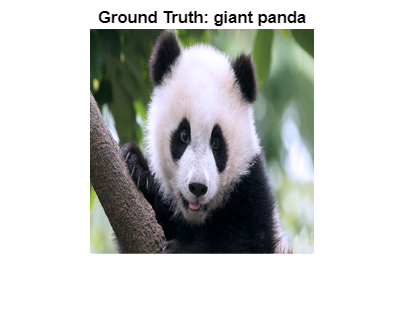

img = imresize(img,inputSize(1:2));

figure;
imshow(img)
title("Ground Truth: " + T)

X = dlarray(single(img),"SSCB");

T = onehotencode(T,1,'ClassNames',classes);

T = dlarray(single(T),"CB");

gradient = dlfeval(@untargetedGradients,dlnet,X,T);

Set `epsilon` to 1 and generate the adversarial example.

epsilon = 1;
XAdv = X + epsilon*sign(gradient);

Predict the class of the original image and the adversarial image.

YPred = predict(dlnet,X);
YPred = onehotdecode(squeeze(YPred),classes,1)

YPred = categorical
     giant panda 


YPredAdv = predict(dlnet,XAdv);
YPredAdv = onehotdecode(squeeze(YPredAdv),classes,1)

YPredAdv = categorical
     lesser panda 


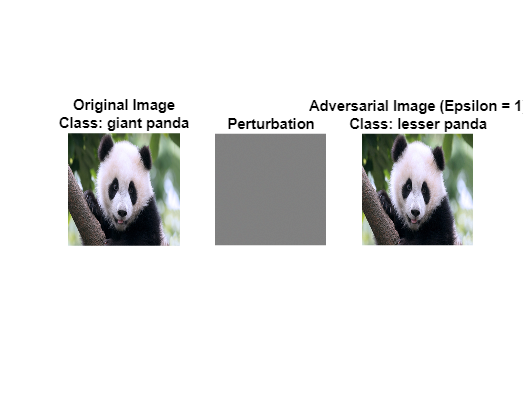

showAdversarialImage(X,YPred,XAdv,YPredAdv,epsilon);

targetClass = "tiger shark";
targetClass = onehotencode(targetClass,1,'ClassNames',classes);

Increase the `epsilon` value to 5, set the step size `alpha` to 0.2, and perform 25 iterations. Note that you may have to adjust these settings for other networks.

epsilon = 4;
alpha = 0.4;
numIterations = 25;

Keep track of the perturbation and clip any values that exceed `epsilon`.

delta = zeros(size(X),'like',X);
for i = 1:numIterations
    gradient = dlfeval(@targetedGradients,dlnet,X+delta,targetClass);
    
    delta = delta - alpha*sign(gradient);
    delta(delta > epsilon) = epsilon;
    delta(delta < -epsilon) = -epsilon;
end

XAdvTarget = X + delta;

Predict the class of the targeted adversarial example.

YPredAdvTarget = predict(dlnet,XAdvTarget);
YPredAdvTarget = onehotdecode(squeeze(YPredAdvTarget),classes,1)

YPredAdvTarget = categorical
     tiger shark 


Display the original image, the perturbation added to the image, and the targeted adversarial image.

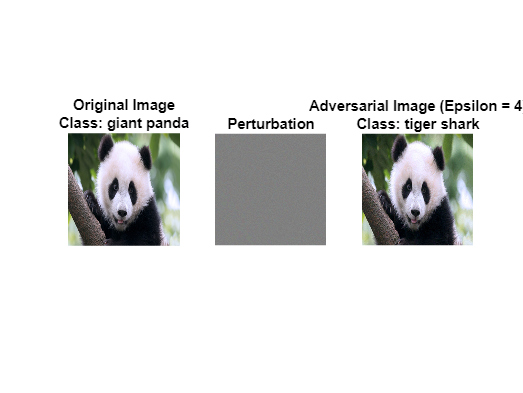

showAdversarialImage(X,YPred,XAdvTarget,YPredAdvTarget,epsilon);

function gradient = untargetedGradients(dlnet,X,target)

Y = predict(dlnet,X);
Y = stripdims(squeeze(Y));
loss = crossentropy(Y,target,'DataFormat','CB');
gradient = dlgradient(loss,X);

end

function gradient = targetedGradients(dlnet,X,target)

Y = predict(dlnet,X);
Y = stripdims(squeeze(Y));
loss = mse(Y,target,'DataFormat','CB');
gradient = dlgradient(loss,X);

end



function showAdversarialImage(image,label,imageAdv,labelAdv,epsilon)

figure
subplot(1,3,1)
imgTrue = uint8(extractdata(image));
imshow(imgTrue)
title("Original Image" + newline + "Class: " + string(label))

subplot(1,3,2)
perturbation = uint8(extractdata(imageAdv-image+127.5));
imshow(perturbation)
title("Perturbation")

subplot(1,3,3)
advImg = uint8(extractdata(imageAdv));
imshow(advImg)
title("Adversarial Image (Epsilon = " + string(epsilon) + ")" + newline + ...
    "Class: " + string(labelAdv))
end